# Process the MRI file segmented by SPM

## Before Using this code, you should complete the segmentation process in SPM.

## What this script will do:

- Find the max probability tissue for each voxel

- Filter the result that have probability <20%.

- Crop the volume

- fillholes3d for tissues, also erosion for scalp.

- Reduce csf thickness.

## How to use this code?

Run each section** one by one**, check the figure to adjust the *numerical slider* or *edit field*, then advance to the next section.

Benjamin Kao

Last update: 2020/08/12

clc;clear;close all;

# Parameters

% to_process_folder={'KB_MRI\t1_mprage_sag_p2_iso_0002'}; % the folder contains the segmented MRI files
to_process_folder={'MRI_raw_datas_2/F_51_60/Y56_F_MINDFUL_CON_10'};

min_probability=51; % =20%, because the value is uint8, 1~256
do_find_sinus=1;
do_find_oil=0;

pre_processed=1; % if =1, use the preprocessed file, otherwise, process the SPM output
use_previous_crop=0; % if =1, use the crop range saved previously
use_previous_sinus=0; % if =1, use the sinus location saved previously
use_previous_oil=0;

# Initialize

currentdir = pwd;

# Main

i=1;

## load segmented file

fprintf('Processing %d / %d folder: %s\n',i,length(to_process_folder),to_process_folder{i});

Processing 1 / 1 folder: MRI_raw_datas_2/F_51_60/Y56_F_MINDFUL_CON_10



cd(fullfile(currentdir,to_process_folder{i}));

## Find the segmented files for each layer and load them

if pre_processed==1
    load('preprocess_maxIndex.mat');
else
    file = dir('c*.nii');
    assert(length(file)==5,['There are more files named ''c*.nii'' in folder ' num2str(i)]);
    
    seg(:,:,:,4) = niftiread(file(1).name); % grey matter
    seg(:,:,:,5) = niftiread(file(2).name); % white matter
    seg(:,:,:,3) = niftiread(file(3).name); % CSF
    seg(:,:,:,2) = niftiread(file(4).name); % skull
    seg(:,:,:,1) = niftiread(file(5).name); % scalp
    
    

## Find the max probabiliry and tissue type for each voxel

Plot for check crop region:


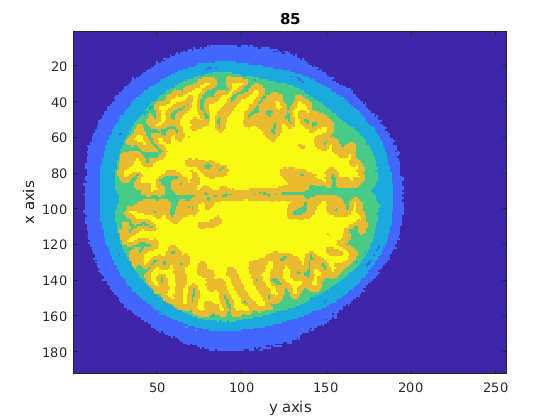

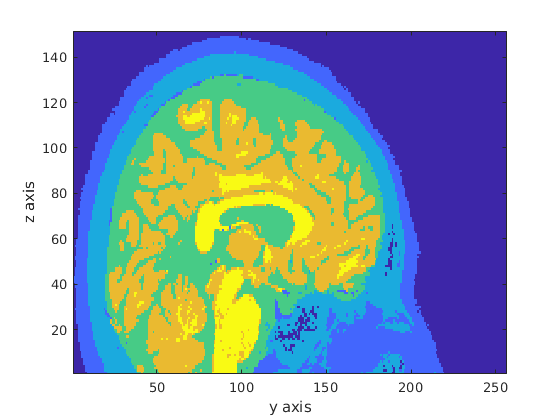

    timer1=tic;
    seg_line=reshape(seg,[],5);
    seg_line=seg_line';
    [max_val,max_index]=max(seg_line);
    max_val=reshape(max_val,size(seg,1),size(seg,2),size(seg,3));
    max_index=reshape(max_index,size(seg,1),size(seg,2),size(seg,3));
    timer1=toc(timer1);
    
    fprintf('finish find value, cost %f secs\n',timer1);
    
    max_val=single(max_val);

## If the probability is too low, set it to tissue 0 (air)

    max_index(max_val<=min_probability) = 0;

## Skip the all 1 slice

    to_resize_z=1;
    while to_resize_z<size(max_index,3)
        if (length(find(max_index(:,:,to_resize_z)==1))/(size(max_index,1)*size(max_index,2)))>0.98
            to_resize_z=to_resize_z+1;
        else
            break;
        end
    end

## Delete the other type of tissue outside scalp

    parfor z=to_resize_z:size(max_index,3)
        fprintf('L %d\n',z);
        temp_slice=max_index(:,:,z);
        index_map=fun_image_seg(temp_slice==1);
        head_mask=imfill(double(index_map==1));
        temp_slice(head_mask~=1)=0;
        max_index(:,:,z)=temp_slice;
    end
end

## Set the volumn to crop

if use_previous_crop==1
    crop_range_arr=load('crop_range.txt');

volume after seting to zero:


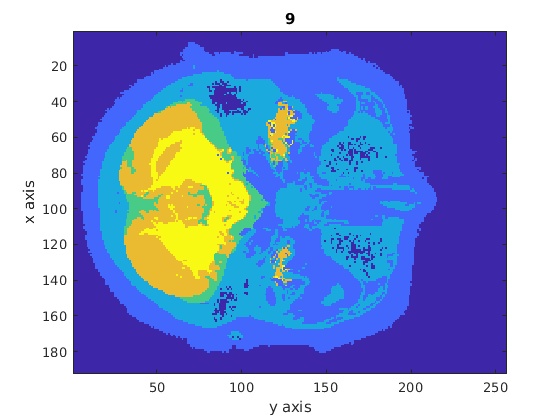

    x_range_1=crop_range_arr(1);
    x_range_2=crop_range_arr(2);
    y_range_1=crop_range_arr(3);
    y_range_2=crop_range_arr(4);
    z_range_1=crop_range_arr(5);
    z_range_2=crop_range_arr(6);

else
    fprintf('Plot for check crop region:\n');
    x_range_1=1;
    x_range_2=192;
    y_range_1=1;
    y_range_2=256;
    z_range_1=85;
    z_range_2=235;
    to_plot_z=85;
    temp_crop_volume=max_index(x_range_1:x_range_2,y_range_1:y_range_2,z_range_1:z_range_2);
    figure;
    imagesc(temp_crop_volume(:,:,to_plot_z));
    title(num2str(to_plot_z));
    axis tight;
    xlabel('y axis');
    ylabel('x axis');
    figure;
    imagesc(squeeze(temp_crop_volume(round(size(temp_crop_volume,1)/2),:,:)));
    view(-90,90);
    axis tight;
    xlabel('z axis');
    ylabel('y axis');
end

	Making mask for layer 1
	Making mask for layer 2
	Making mask for layer 3
	Making mask for layer 4
	Making mask for layer 5


## Crop the volumn

max_index=max_index(x_range_1:x_range_2,y_range_1:y_range_2,z_range_1:z_range_2);

The tissue after fill holes


to_save=[x_range_1 x_range_2 y_range_1 y_range_2 z_range_1 z_range_2];
save('crop_range.txt','to_save','-ascii','-tabs');

## Set the region to be Zero

Because there are some artifact, we should set it to zero

if use_previous_crop
    load('to_zero_setting.mat');
else
    to_zero_center={[0,250,1]}; % [0 220 0],[0 190 0],[0 150 15]
    to_zero_radius={0}; % 30,30,15
end

## Set the volume to Zero

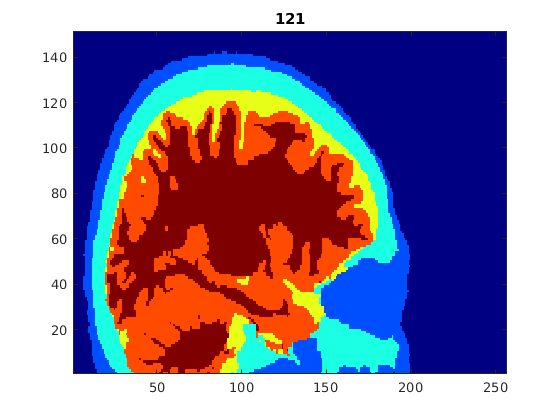

temp_to_zero_volume=max_index;

[xx,yy,zz]=ndgrid(1:size(temp_to_zero_volume,1),1:size(temp_to_zero_volume,2),1:size(temp_to_zero_volume,3));
assert(length(to_zero_center)==length(to_zero_radius),'to zero region setting ERROR!');
for z=1:length(to_zero_center)
    temp_to_zero_volume(((xx-to_zero_center{z}(1)).^2+(yy-to_zero_center{z}(2)).^2+(zz-to_zero_center{z}(3)).^2)<=to_zero_radius{z}^2)=0;

Thinning the CSF layer


end

% save
save('to_zero_setting.mat','to_zero_radius','to_zero_center');

plot

to_plot_z=9;

The tissue after thinning CSF


fprintf('volume after seting to zero:\n');
figure;
imagesc(temp_to_zero_volume(:,:,to_plot_z));
title(num2str(to_plot_z));
xlabel('y axis');
ylabel('x axis');
axis tight;

## Confirm the setting

max_index=temp_to_zero_volume;

## Making the mask for each layer

For fill hole and thinning process

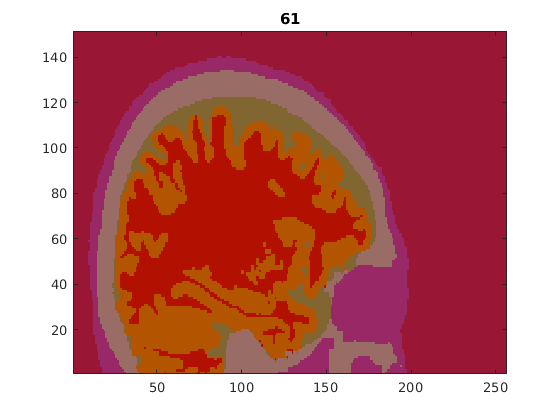

tissue_mask=[];
for tissue_i = 1:5
    fprintf('\tMaking mask for layer %d\n',tissue_i);

    ss=max_index;
    ss(max_index>=tissue_i)=1;
    ss(max_index<tissue_i)=0;
    if tissue_i==2
        tissue_mask(:,:,:,tissue_i) =fillholes3d(ss,5);
    else
        tissue_mask(:,:,:,tissue_i) = fillholes3d(ss,2);
        if tissue_i==1
            kernel_r=3;
            [xx,yy,zz] = ndgrid(-kernel_r:kernel_r);
            kernel = sqrt(xx.^2 + yy.^2 + zz.^2) <= kernel_r; % the kernel for 3D erosion
            tissue_mask(:,:,:,tissue_i)=imerode(tissue_mask(:,:,:,tissue_i),kernel);
        end
    end
end

plot

fprintf('The tissue after fill holes\n');
to_plot_x=121;
tissue_type = sum(tissue_mask,4);
figure;
imagesc(squeeze(tissue_type(to_plot_x,:,:)));
title(num2str(to_plot_x));
view(-90,90);
axis tight;
colormap jet;
caxis([0,5]);
%     keyboard;

## Thinning the CSF layer

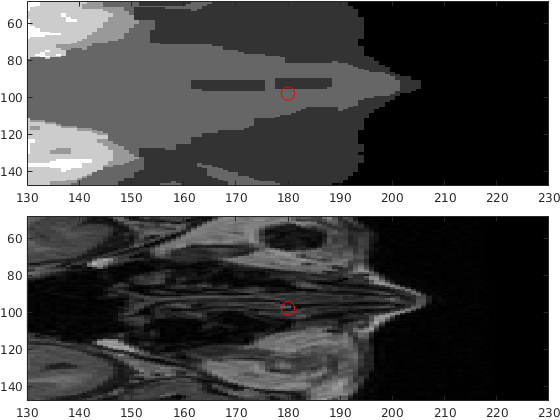

fprintf('Thinning the CSF layer\n');
% vol=thinbinvol(tissue_mask(:,:,:,3),2);
vol=tissue_mask(:,:,:,3);

plot

The yellow part is the difference between original CSF layer and the thinned CSF layer.

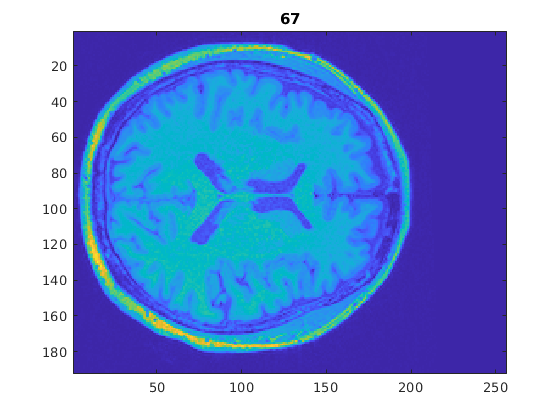

fprintf('The tissue after thinning CSF\n');
figure;
to_plot_x=61;
imagesc(squeeze(tissue_type(to_plot_x,:,:)));
view(-90,90);
hold on
imagesc(squeeze(vol(to_plot_x,:,:)+5),'AlphaData',0.6)
title(num2str(to_plot_x));
hold off
axis tight;
colormap jet;
caxis([0,6]);
tissue_mask(:,:,:,3) = vol;
%     keyboard;

## Assign the tissue index for the final version

tiss = zeros(size(max_index));
for tissue_i = 1:5
    tiss(tissue_mask(:,:,:,tissue_i)>0)=tissue_i;
end

## Load the original MRI image and crop it

Notice that if you use the spatial normalized file to segment, you should choose the corresponding file.

% file = dir(fullfile(to_process_folder{i},'r*.nii'));
file = dir('w*.nii');
if length(file)==0
    file = dir('r*.nii');
    if length(file)==0
        file = dir('s*.nii');
    end
end
assert(length(file)==1,['There are more files named ''r*.nii'' in folder ' num2str(i)]);
% orig_image = niftiread(fullfile(to_process_folder{i},file.name));
orig_image = niftiread(file.name);

orig_image=orig_image(x_range_1:x_range_2,y_range_1:y_range_2,z_range_1:z_range_2); % crop

## Find the sinus and delete it

First,  find the location of sinus manually.

if use_previous_sinus
    load('sinus_setting.mat');
else
    sinus_pos=[180,98,22];
    radius_to_show=50;
end
    
if do_find_sinus
    % plot the pos of sinus center
    figure();
    ti=tiledlayout('flow','TileSpacing','compact','Padding','none');
    nexttile(1);
    imagesc(tiss(:,:,sinus_pos(3)));
    hold on;
    plot(sinus_pos(1),sinus_pos(2),'or','MarkerSize',10);
    xlim([sinus_pos(1)-radius_to_show,sinus_pos(1)+radius_to_show]);
    ylim([sinus_pos(2)-radius_to_show,sinus_pos(2)+radius_to_show]);
    
    nexttile(2);
    imagesc(orig_image(:,:,sinus_pos(3)));
    colormap gray;
    hold on;
    plot(sinus_pos(1),sinus_pos(2),'or','MarkerSize',10);
    xlim([sinus_pos(1)-radius_to_show,sinus_pos(1)+radius_to_show]);
    ylim([sinus_pos(2)-radius_to_show,sinus_pos(2)+radius_to_show]);
end

### Find the sinus on the original image

if use_previous_sinus==0
    sinus_radius=45;
    sinus_treshold=80;
end

if do_find_sinus
    figure();
    for z=max(sinus_pos(3)-sinus_radius,1):min(sinus_pos(3)+sinus_radius,size(orig_image,3))
        temp_layer=orig_image(:,:,z);
        [xx,yy]=ndgrid(1:size(temp_layer,1),1:size(temp_layer,2));
        dist2sinus=sqrt((yy-sinus_pos(1)).^2+(xx-sinus_pos(2)).^2+(z-sinus_pos(3))^2); % switch the x and y
        temp_layer(dist2sinus<sinus_radius & temp_layer<sinus_treshold & tiss(:,:,z)==2)=max(temp_layer(:));
        imagesc(temp_layer);
        title(num2str(z));
        drawnow;
        pause(0.1);
    end
end

### Confirm the sinus change

if do_find_sinus
    [xx,yy]=ndgrid(1:size(tiss,1),1:size(tiss,2));
    for z=max(sinus_pos(3)-sinus_radius,1):min(sinus_pos(3)+sinus_radius,size(orig_image,3))

There are 56385 voxels changed index.


        temp_slice=tiss(:,:,z);

There are 0 voxels changed from 0 to tissue.


        dist2sinus=sqrt((yy-sinus_pos(1)).^2+(xx-sinus_pos(2)).^2+(z-sinus_pos(3))^2); % switch the x and y
        temp_slice(dist2sinus<sinus_radius & orig_image(:,:,z)<sinus_treshold & tiss(:,:,z)==2)=6;
        tiss(:,:,z)=temp_slice;

There are 3665 voxels changed.


    end
    save('sinus_setting.mat','sinus_pos','sinus_radius','sinus_treshold','radius_to_show');
end

## Find the oil and delete it

First,  find the location of sinus manually.

if use_previous_oil
    load('oil_setting.mat');
else
    oil_pos=[177,158,80];
    radius_to_show=50;
end
    
if do_find_oil

Ploting the segmented result


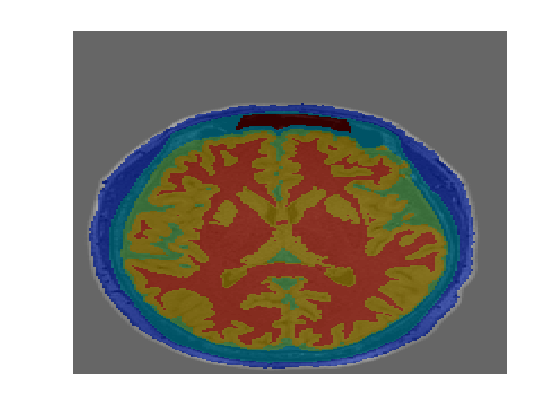

    % plot the pos of sinus center
    figure();
    ti=tiledlayout('flow','TileSpacing','compact','Padding','none');
    nexttile(1);
    imagesc(tiss(:,:,oil_pos(3)));
    hold on;
    plot(oil_pos(1),oil_pos(2),'or','MarkerSize',10);
    xlim([oil_pos(1)-radius_to_show,oil_pos(1)+radius_to_show]);
    ylim([oil_pos(2)-radius_to_show,oil_pos(2)+radius_to_show]);
    
    nexttile(2);
    imagesc(orig_image(:,:,oil_pos(3)));

    colormap gray;
    hold on;
    plot(oil_pos(1),oil_pos(2),'or','MarkerSize',10);
    xlim([oil_pos(1)-radius_to_show,oil_pos(1)+radius_to_show]);

Save segmented result to file


    ylim([oil_pos(2)-radius_to_show,oil_pos(2)+radius_to_show]);
end

### Find the oil on the original image

if use_previous_oil==0

Save segmented result to animation


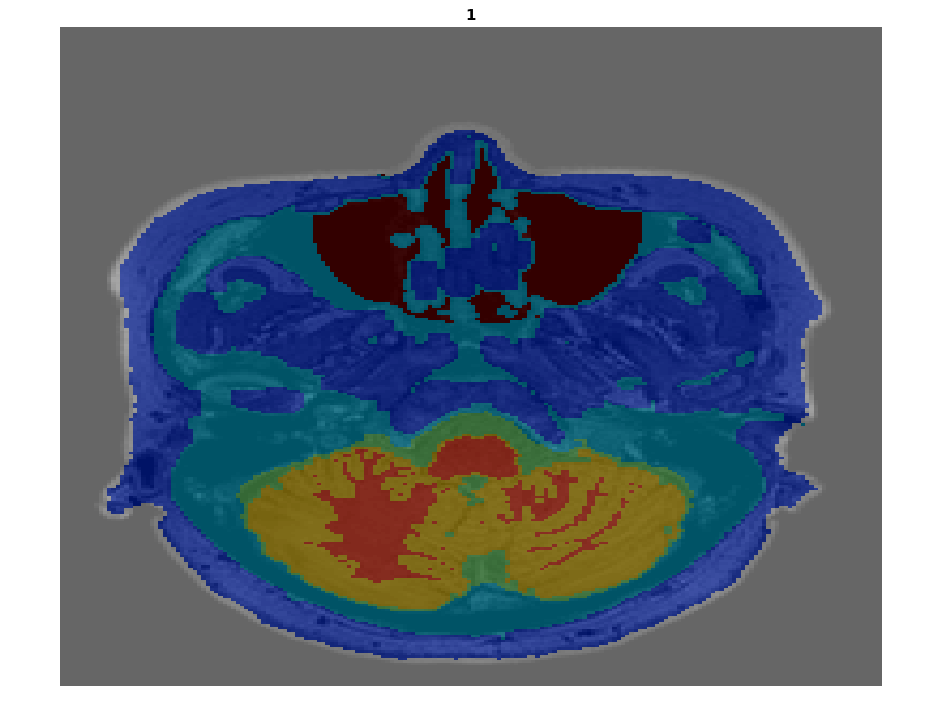

    oil_radius=15;

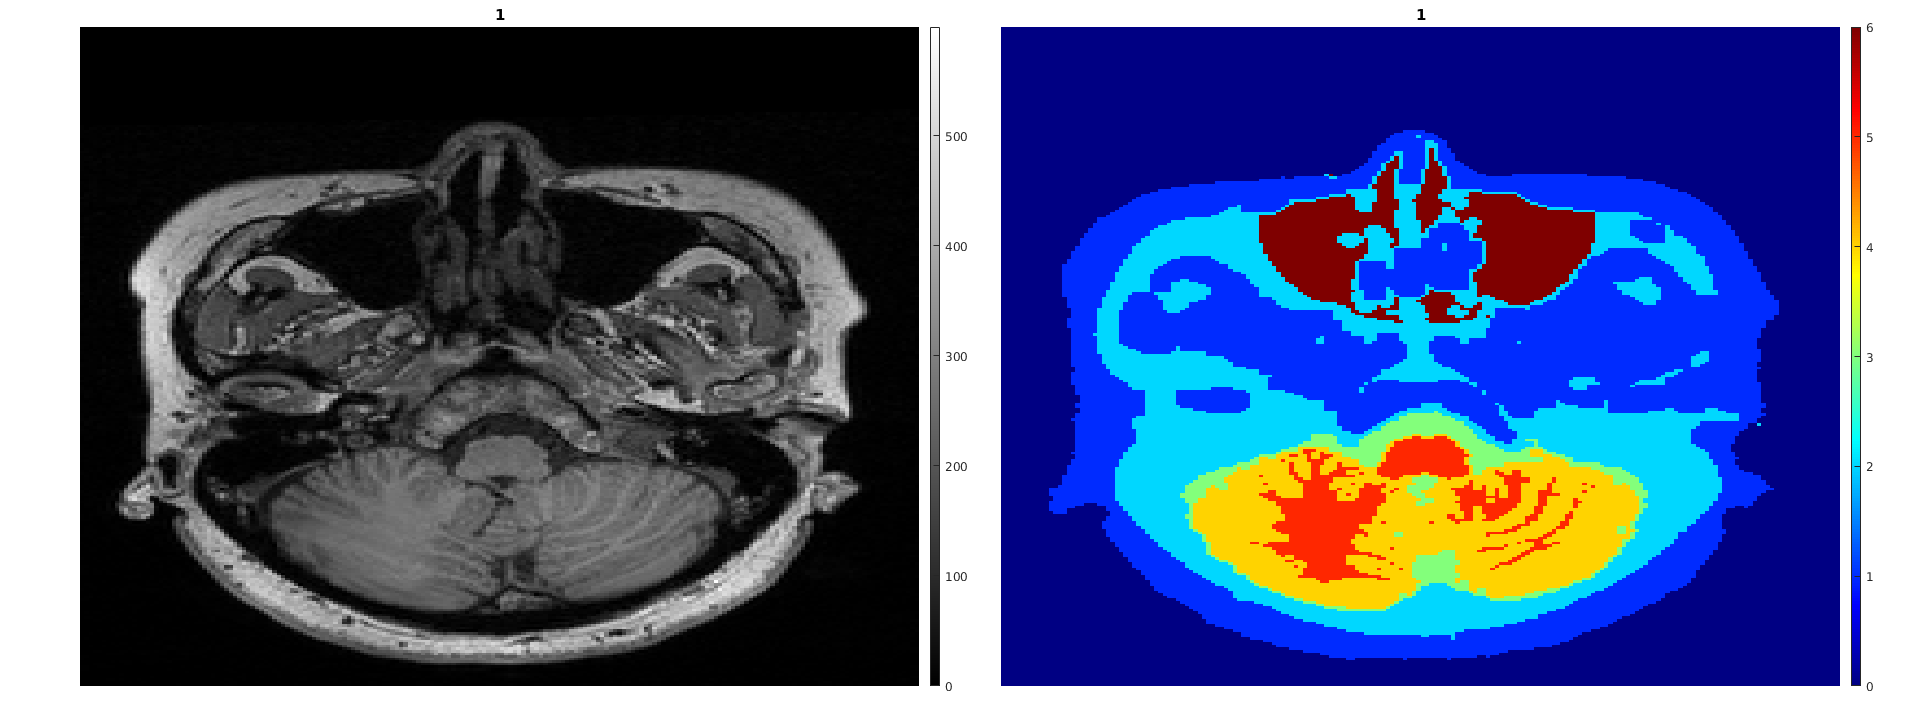

    oil_treshold=500;

end

if do_find_oil
    figure();

Done!


    for z=max(oil_pos(3)-oil_radius,1):min(oil_pos(3)+oil_radius,size(orig_image,3))
        temp_layer=orig_image(:,:,z);
        [xx,yy]=ndgrid(1:size(temp_layer,1),1:size(temp_layer,2));
        dist2sinus=sqrt((yy-oil_pos(1)).^2+(xx-oil_pos(2)).^2+(z-oil_pos(3))^2); % switch the x and y
        temp_layer(dist2sinus<oil_radius & temp_layer>oil_treshold & tiss(:,:,z)==1)=max(temp_layer(:));
        imagesc(temp_layer);
        title(num2str(z));
        drawnow;
        pause(0.1);
    end
end

### Confirm the oil change

if do_find_oil
    smooth_dilate_kernel=strel('sphere',10);
    [xx,yy]=ndgrid(1:size(tiss,1),1:size(tiss,2));
    for z=max(oil_pos(3)-oil_radius,1):min(oil_pos(3)+oil_radius,size(orig_image,3))
        temp_slice=tiss(:,:,z);
        dist2sinus=sqrt((yy-oil_pos(1)).^2+(xx-oil_pos(2)).^2+(z-oil_pos(3))^2); % switch the x and y
        temp_slice(dist2sinus<oil_radius & orig_image(:,:,z)>oil_treshold & tiss(:,:,z)==1)=0;
%         tiss(:,:,z)=temp_slice;
        temp_slice_mask=double(temp_slice>0);
        temp_slice_mask=imopen(temp_slice_mask,smooth_dilate_kernel);
        temp_slice(temp_slice_mask==0)=0;
        tiss(:,:,z)=temp_slice;
    end
    save('oil_setting.mat','oil_pos','oil_radius','oil_treshold','radius_to_show');
end

### Fill holes

tiss=fillholes3d(tiss,2);

### Make sure the outer layer enclosuer the inner layer

new_vol=tiss;

dilate_kernel=strel('sphere',1);
skull_dilate_kernel=strel('sphere',2);

for L=5:-1:1
    before_vol=new_vol;
    temp_tissue_vol=new_vol==L;
    if L==3
        temp_tissue_dil=imdilate(temp_tissue_vol,skull_dilate_kernel);
    else
        temp_tissue_dil=imdilate(temp_tissue_vol,dilate_kernel);
    end
    tissue_boundary=temp_tissue_dil-temp_tissue_vol;
    
    if L==2
        new_vol(new_vol==1 & tissue_boundary==1)=1;
        new_vol(new_vol==6 & tissue_boundary==1)=2;
    elseif L==1
        new_vol(new_vol==6 & tissue_boundary==1)=2;
    else
        new_vol((new_vol<=L-1 | new_vol==6) & tissue_boundary==1)=L-1;
    end    
end

temp_vol=tiss>0;
temp_new_vol=new_vol>0;
fprintf('There are %d voxels changed index.\n',length(find(new_vol-tiss)));
fprintf('There are %d voxels changed from 0 to tissue.\n',length(find(temp_new_vol-temp_vol)));

new_new_vol=fillholes3d(new_vol,2);
fprintf('There are %d voxels changed.\n',length(find(new_new_vol-new_vol)));
tiss=new_new_vol;

### prepare for plot

seged_arr = (tiss/max(tiss(:))*64)+64;

orig_image_to_plot = double(orig_image);
orig_image_to_plot = (orig_image_to_plot/1234*64);

## Compare the segmented result to the MRI image

plot

fprintf('Ploting the segmented result\n');
figure();
colormap([gray(64);jet(64)]);

to_plot_z=58;
imagesc(squeeze(orig_image_to_plot(:,:,to_plot_z)))
hold on
imagesc(squeeze(seged_arr(:,:,to_plot_z)),'AlphaData',0.4)
hold off
view(-90,90)
axis off
caxis([1 128])
axis tight;

## Save the final version and animation to file

If the above result is *Okey*, then run this section.

fprintf('Save segmented result to file\n');
niftiwrite(tiss,'segmented_tissue');
cd(currentdir)

fprintf('Save segmented result to animation\n');
plot_segmented_slice_orig(tiss,orig_image,fullfile(to_process_folder{i},'segmented_tissue_orig.avi'));
plot_segmented_slice_orig_subplot(tiss,orig_image,fullfile(to_process_folder{i},'segmented_tissue_compare.avi'));

close all;

disp('Done!');


# Functions

function plot_segmented_slice_orig(seged_arr,orig_image,to_save_filename)
if nargin>2
    v = VideoWriter(to_save_filename);
    v.FrameRate=10;
    open(v);
end

seged_arr = (seged_arr/max(seged_arr(:))*64)+64;

orig_image = double(orig_image);
orig_image = (orig_image/1234*64);

f=waitbar(0,'ploting');

% figure('units','normalized','outerposition',[0 0 0.7 1]);
figure('Units','pixels','position',[0 0 926 726]);
ti=tiledlayout(1,1,'TileSpacing','compact','Padding','compact');
nexttile(1);
for i=1:size(seged_arr,3)
    waitbar(i/size(seged_arr,3),f,['plot ' num2str(i) '/' num2str(size(seged_arr,3))]);
    colormap([gray(64);jet(64)]);
    imagesc(squeeze(orig_image(:,:,i)));
    hold on
    imagesc(squeeze(seged_arr(:,:,i)),'AlphaData',0.4);
    hold off
    view(-90,90)
    axis off
    caxis([1 128])
    axis tight;
    title(num2str(i));
    
    drawnow;
    if nargin>2
        frame = getframe(gcf);
        writeVideo(v,frame);
    end
end
if nargin>2
    close(v);
end
delete(f);
end

function plot_segmented_slice_orig_subplot(seged_arr,orig_image,to_save_filename)
if nargin>2
    v = VideoWriter(to_save_filename);
    v.FrameRate=10;
    open(v);
end

f=waitbar(0,'ploting');
% figure('units','normalized','outerposition',[0 0 1 0.7]);
figure('Units','pixels','position',[0 0 1920 726])
ti=tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
for i=1:size(seged_arr,3)
    waitbar(i/size(seged_arr,3),f,['plot ' num2str(i) '/' num2str(size(seged_arr,3))]);
    nexttile(1);
    imagesc(squeeze(orig_image(:,:,i)));
    view(-90,90);
    axis off
    colormap(gca,'gray');
    axis tight;
    colorbar;
    title(num2str(i));
    
    nexttile(2);
    imagesc(squeeze(seged_arr(:,:,i)));
    view(-90,90);
    axis off
    colormap(gca,'jet');
    caxis([0 max(seged_arr(:))]);
    axis tight;
    colorbar;
    title(num2str(i));
    
    drawnow;
    if nargin>2
        frame = getframe(gcf);
        writeVideo(v,frame);
    end
end
if nargin>2
    close(v);
end
delete(f);
end